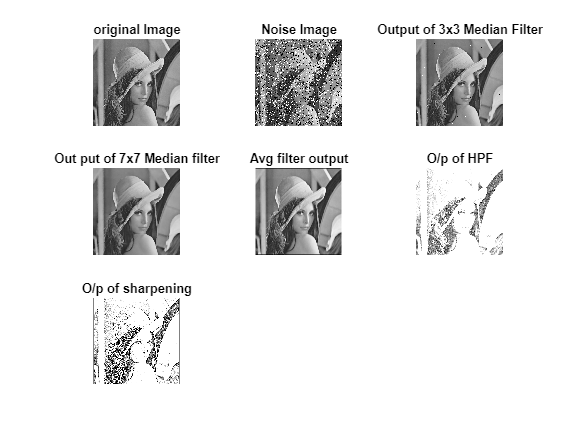

clc;
clear all;
close all;



subplot(3,3,1);
a=imread("lena_gray.jpeg");
imshow(a);
title('original Image');



subplot(3,3,2);
j=imnoise(a,'salt & pepper',0.2);
imshow(j);
title('Noise Image');



subplot(3,3,3);
k=medfilt2(j,[3 3]);
imshow(k);
title('Output of 3x3 Median Filter')



subplot(3,3,4)
k1=medfilt2(j,[7 7]);
imshow(k1);
title('Out put of 7x7 Median filter')



subplot(3,3,5);
avgfilt=[1 1 1 1 1 1 1;
1 1 1 1 1 1 1;
1 1 1 1 1 1 1;
1 1 1 1 1 1 1;
1 1 1 1 1 1 1;
1 1 1 1 1 1 1;
1 1 1 1 1 1 1;
];
avgfiltmask = avgfilt/sum(avgfilt);
convimage=conv2(double(a),double(avgfiltmask));
imshow(convimage,[]);
title('Avg filter output')



subplot(3,3,6)
h=[1 -2 1;-1 3 -1;1 -2 1];
hpt3=conv2(double(a),double(h));
imshow(hpt3/100);
title('O/p of HPF')



subplot(3,3,7)
h1=[-1 -1 -1;-1 9 -1;-1 -1 -1];
hpt32=conv2(double(a),double(h1));
imshow(hpt32/100);
title('O/p of sharpening');